# Visualize Elementary Flux Modes from Human model 

## Author(s): Chaitra Sarathy (Maastricht University, The Netherlands)

## Reviewer(s): 

*Include those who have reviewed the tutorial, and are therefore partly responsible for picking up errors or omissions.*

## INTRODUCTION

Elementary Flux Modes (EFMs) are a tool for constraint-based modelling and metabolic network analysis. However, systematic and automated visualization of EFMs, capable of integrating various data types is still a challenge. This tutorial is part of the study by Sarathy et al. (2019, in preparation), "An integrative workflow to visualize Elementary Flux Modes in genome-scale metabolic models". 

This workflow can be used to visualize EFMs calculated using any currently available methods. Inputs for the workflow are: (1) the text file containing EFMs and (2) the genome-scale metabolic model used for generating EFMs. Additionally, omics data can be used to select one (or more) EFM(s) for visualization among the vast number of EFMs that usually results from EFM calculation. Sarathy et al. (2019, in preparation) demonstrate two examples of such a selection procedure (a) Yield Analysis and (b) EFM Enrichment with EFMs calculated from genome-scale metabolic models, (1) iAF1260 (E. coli) [1] and (2) Recon 2.2 (Human) [2]. 

Each use case is explained with a tutorial. This tutorial corresponds to the second use case and it describes how to analyze and visualize EFMs from the human model Recon 2.2*. *The aim is to apply the workflow on a large-scale model and it can be used as a means to study cancer metabolism. EFMs were generated for glucose uptake reaction. For details on how EFMs were generated, please refer the citation section at [https://github.com/macsbio/efmviz](https://github.com/macsbio/efmviz)

The steps in the workflow include:

        **A. Specifying Inputs**

        i. Import input data: file containing EFMs (.txt), model file (.mat), file containing gene level statistics typically resulting from a differential gene expression analysis (.txt)

       ** B. EFM Selection**

        i. Filter EFMs containing a reaction of interest

        ii. Perform EFM Enrichment Analysis

            a. Generate input files for EFM Enrichment (preprocessing)

            b. Call R script for Enrichment (EFM_enrichment.R)

        iii. EFM Selection

            a. Get indices of enriched EFMs 

            b. Find Subsystem Occurrence in enriched EFMs for selecting an EFM for visualization, for example, EFM with reactions in TCA Cycle

        **C. Submodel Creation**

        i. Write submodel (with ubiquitous metabolites)

        ii. Write submodel (withOUT ubiquitous metabolites)

        iii. Extract reactions occurring in a certain percentage of EFMs

        **D. Visualization**

        Open the SBML file in Cytoscape and map the data used during step B.

The following sections will walk you through the code for performing the steps A-D, thereby reproducing the main results from Sarathy et al (2019, in preparation) (Use Case 2). For more details on the workflow please refer [https://github.com/macsbio/efmviz](https://github.com/macsbio/efmviz)

**Input File Formats**

- model (.mat): same as the model used for EFM generation 

- file containing EFMs (.txt): each row corresponds to an EFM and column has indices of reactions active in the EFM. Each row can have varied number of columns. The first column should contain an EFM ID.

- file containing gene level statistics (.txt): Tab separated file containing an expression level (log2 fold change) and p-value for every gene. Columns: <GeneID><GeneName><log2FC><PValue>. Make sure to have the gene IDs in the same format as in the model.

## PROCEDURE

## *A. Specifying Input* 

First, declare all the input variables such as file paths and filenames of input files and output files.

% File names and location
modelFileLocation = strcat(pwd, '\inputs\'); 
modelFileName = 'recon2_2_irr.mat';

efmFileLocation = strcat(pwd, '\inputs\');
efmFileName = 'EFM-Dglucose-E10000-10757.txt';

geneStatFlieLocation = strcat(pwd, '\inputs\');
geneStatFileName = 'data_useCase_2.txt';

% Prefixes for the output files 
organism = 'human';
dataFile = 'dataForMapping_EFM';
efmBackboneFile = 'efmBackbone';
efmPercentage = '_EFMBackbone_percentage_';
dataFileExt = '.txt';
sbmlExt = '.xml';
efmPre = '_EFM_';
metRem = '_woUbMet_';

% Output file names
GSCFileName = strcat('GSC-', organism, dataFileExt); 
GSSFileName = strcat('GSS-', organism, dataFileExt); 

Also define the numeric indices of reactions of interest i.e., acetate release and glucose uptake, which will be used for calculating yield.

roi_glcUp = 10757; % glucose uptake (EX_glc(e)_b, also the active reaction for EFM Generation)
roi_lacRel = 6613; % lactate release, EX_lac_L(e)_f

If you know the reaction ID from the model, the corresponding index can be calculated as:

% index = find(contains(model_irr.rxns, 'EX_lac_L(e)_f')); % gives 6613 as output

***i. Import model, EFMs and gene level statistics***

Load the same model that was used for generating set of EFMs. Here, Recon 2.2 was converted to a model containing only unidirectional (irreversible) reactions for EFM calculation.

model_irr = importdata([modelFileLocation modelFileName]);

Alternatively, xml model file can also be used. In that case, use the COBRA function *readCbModel.*

Next, import the files containing EFMs. 

EFMRxns = efmImport(efmFileLocation, efmFileName);

Also, load the text file containing gene level statistics

geneData = readtable([geneStatFlieLocation geneStatFileName]); 

**TIMING**: For large models and large set of EFMs, this step can take a few seconds to couple of minutes.

## *B. EFM Selection*

***i. Filter EFMs***

Next, retain EFMs containing the acetate release reaction for further analysis.

[filteredEFMs, filteredRows] = efmFilter(EFMRxns, roi_lacRel); 

This results in 19 EFMs containing both glucose uptake and lactate release reactions. If large number of EFMs still remain, the above step can be repeated with additional reactions of interest.

***ii. EFM Enrichment***

Enrichment is a two-step process consisting of preprocessing and enrichment analysis. Preprocessing will be done in MATLAB and enrichment itself will be done in R using the function 'runGSA()' which is a part of piano package [3]. Piano is useful for performing an enrichment analysis using custom gene sets.   

***a. Generate input files for EFM Enrichment (preprocessing)***

The function runGSA() requires two input files - Gene Set Collection (GSC) and Gene Set Statistics (GSS). 

GSC file: The gene set collection should describe the grouping of genes into gene sets. In this case, each EFM itself will be a set containing the reactions. A two-column (space-separated) file: <EFM name or number> and <reaction ID> will be generated.

GSS file:  The gene set collection should contain a p-value and expression value for each gene. Since our sets contain reactions, the gene level statistics will be mapped onto the reactions using the GPR rules defined in the model. A three-column (space-separated) file: <reaction ID> <fold change> <p value> will be generated.

% create the expreData variale with specific fields (gene, value, sig) as required by COBRA functions that map expression from genes to reactions
exprData.gene = geneData.GeneID;
exprData.value = geneData.log2FC;
exprData.sig = geneData.PValue;
% exprSig = geneData.PValue;
minSum = false;

% efmEnrichmentAnalysis(filteredEFMs,model_irr, exprData, GSCFileName, GSSFileName);  
efmEnrichmentAnalysis1(filteredEFMs, model_irr, exprData, GSCFileName, GSSFileName, minSum)

Once the input files needed for enrichment are written out, call the R script for performing enrichment.

***b. Call R script for Enrichment***

**NOTE**: Modifiy the R directory according to the version of R installed on your system, if necessary.

% ! "C:\Program Files\R\R-3.5.1\bin\Rscript.exe" EFM_enrichment.R
! "C:\Program Files\R\R-3.5.0\bin\Rscript.exe" EFM_enrichment.R

Loading required package: piano 
Running gene set analysis:
Checking arguments...done!
Final gene/gene-set association: 2192 genes and 19 gene sets
  Details:
  Calculating gene set statistics from 2192 out of 11567 gene-level statistics
  Using all 11567 gene-level statistics for significance estimation
  Removed 0 genes from GSC due to lack of matching gene statistics
  Removed 0 gene sets containing no genes after gene removal
  Removed additionally 0 gene sets not matching the size limits
  Loaded additional information for 0 gene sets
Calculating gene set statistics...done!
Calculating gene set significance...done!
Adjusting for multiple testing...done!


An output file "EFMEnrichmentResults.xls" will be written in the working directory. 

**TIMING**: Enrichment - Preprocessing and running the R script could take a few minutes.

**TROUBLESHOOTING:** Check the location where R is installed in your system. If different from the code above, replace the path.

***iii. EFM Selection***

***a. Get indices of enriched EFMs ***

Inspect the resulting file to select the most significant EFM(s).

upIndices = [83 29 42 28 51 84 41 69 70 79 82 62 36 35 12 39 64];

***b. Find Subsystem Occurrence in enriched EFMs and plot***

Once you have identified the most significant EFMs, extract the distribution of subsystems to select an EFM to visualize.

upEFMs = EFMRxns(upIndices, :);
[subsysSummaryUp, uniqSubsysUp, countSubPerEFMUp] = efmSubsystemsExtraction(model_irr, upEFMs);

for tt=1:size(upEFMs, 1)
   len(tt) = length(find(upEFMs(tt,:))) ;
end

countPerLenUp = countSubPerEFMUp ./ len;
for tt = 1:size(countPerLenUp,1)
    rowZeros(tt) = length(find(countPerLenUp(tt,:)==0));
end
countPerLen_filtered = countPerLenUp(rowZeros < size(upEFMs,1)-round(0.5*size(upEFMs,1)),:);
uniqSubsysLeu_filtered = uniqSubsysUp(rowZeros < size(upEFMs,1)-round(0.5*size(upEFMs,1)),:);

**CAUTION**: DO NOT CLICK ON RUN! (FOR THIS SECTION ONLY)

Select the below code for plotting and press F9

Error using uimenu
First argument must be a valid parent, such as a Figure or Panel object.

Error in clustergram/view>updateUIMenus (line 149)
uimenu(hw ,'Label','Print to Figure',...

Error in clustergram/view (line 61

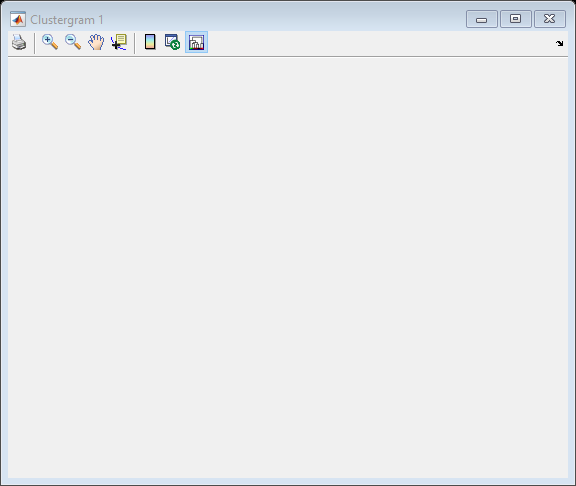

g3=clustergram(countPerLen_filtered);

g3.Colormap=flipud(summer(500));
g3.Cluster=3;
g3.Symmetric=false;
g3.DisplayRange=60;
g3.ColumnLabels=cellstr(strcat("EFM", string(upIndices)));
g3.RowLabels=cellstr(uniqSubsysLeu_filtered);
g3.Colormap(1,:) = [1, 1, 1];
g3.ColumnLabelsRotate = 30;
addTitle(g3, "Subsystem Occurrence in EFMs containing Glucose uptake and Leucine release ");


As seen from the plot, EFM 83 is the shortest and stands out due to its highest density of reactions in Glycolysis/gluconeogenesis and Galactose metabolism and thus, was selected for visualization

selectedEFM = 83;

Once you have selected an EFM, you can extract the reactions in the EFM as a submodel (SMBL file) as explained below in C (Submodel Creation). This SBML file will be imported into Cytoscape in step D. You can choose to extract the SBML file with or without molecules that are connected to several reactions such as ATP and H2O using step C.i. or C.ii. respectively. We reccommend removing highly connected metabolites to improve the readability of the visualized network. In cases of analyzing/visualizing several EFMs, you can first visualize without ubquitous molecules to understand the underlying process and then look at the corresponding network with ubiquitous molecules.

An SBML file will be generated as output in each substep - C.i., C.ii. and C.iii. You can choose to run one step at a time. Follow the instructions in step D for each SBML file that you want to visualize.

## *C. Submodel Creation*

***i. Write submodel (with ubiquitous metabolites)***

Get the indices of all reactions present in the selected EFM and extract it as a SBML file.

selectedRxns = EFMRxns(selectedEFM, find(EFMRxns(selectedEFM,:))); 
efmSubmodelExtractionAsSBML(model_irr, selectedRxns, char(strcat(organism, efmPre, string(selectedEFM), sbmlExt)));

SBML file with all the metabolites is written in the current working directory.

**TIMING**: Writing SBML file could take a few seconds

***ii. Write submodel (withOUT ubiquitous metabolites)***

Define the list of ubiquitous metabolites to be removed, making sure that the metabolite IDs match those in the model. Extract it as a SBML file

ubiquitousMets = {'h';'h2';'h2o';'atp';'pi';'adp';'nad';'ppi';'pppi';'nadh';'nadp';'nadph';'amp';'co2';'coa';'nh4';'o2';'fad';'fadh2';'fe2';'fe3';'na1';'gdp';'gtp';'udp';'ctp';'utp';'cdp';'fmn';'fmnh2'};
efmSubmodelExtractionAsSBML(model_irr, selectedRxns, char(strcat(organism, efmPre, string(selectedEFM), metRem, sbmlExt)), 1, ubiquitousMets);

SBML file withOUT all the specified metabolites is written in the current working directory.

In addition to looking at single EFMs, you can also use this workflow to extract an "EFM Backbone", i.e., commonly occurring reactions in the EFMs A certain percentage can be used as an input criteria , for example, 80%, 50%, 25%.

***iii. Extract reactions occurring in a certain percentage of EFMs***

First, set the desired percentage and extract the reactions that are present in 'percentage' of EFMs. Input this set of reactions to the function 'efmSubmodelExtractionAsSBML' to write it out as an SBML file.

percentage = 40;
[selectedRxns,  rxnDistribution] = efmBackboneExtraction(filteredEFMs, percentage);
% x = h.BinEdges;
% y = h.Values;
% text(x(1:end-1)
rxnDistribution.rxnName = model_irr.rxns(rxnDistribution.rxnID);
efmSubmodelExtractionAsSBML(model_irr, selectedRxns.rxnID, char(strcat(organism, efmPercentage, string(percentage), sbmlExt)), 1, ubiquitousMets);

% % [OPTIONAL] Plot the number of reactions present in different proportion of EFMs and save this data in a text and map on visualized network
% figure; h = his,y,num2str(y'),'vert','bottom','horiz','left');
% writetable(rxnDistribution, strcat(organism, dataFile, '_', efmBackboneFile, dataFileExt));

Note: The tutorial on use case 1 included an additional optional step here to extract flux data for mapping. Apart from flux data, you can also map gene expression data on the visualized network for which, the same input file from step B can be used. 

## D. Visualization

Follow these steps for each submodel SBML file that you wish to visualize.

- Make sure Cytoscape (v3 and above) is installed along with cy3sbml (app) and yFiles layout

- Open the SBML file using the cy3sbml app. [Click on the cy3sbl app-specific icon and select the EFM submodel file to open. For every file imported, three networks are generated and are identified using the prefixes: All, Base and Kinetic. Use the Base network for rest of the tutorial.

- Import the style file supplied with this workflow (efmviz_style.xml) and apply this style on the Base network. You can now see a network with three different types of nodes representing reactions, genes and metabolites and edges representing interaction between these molecule types. This is how your EFM looks!

- Set the layout using Layout -> yFiles Orthogonal layout. In our experience orthogonal layout works best for EFMs with 50-60 reactions. Beyond that, the EFM can be visualized, but will be difficult to interpret.

- (Optionally) Import the data file generated in step C.iv to map on the reaction edges. Use the R script (see below for details)

For running this step on several files, follow instructions in the R script, efmviz_rcy3_human.Rmd. 

**Try it yourself****:** Repeat steps C and D for other EFMs.

## REFERENCES

[1] Feist, A.M.; Henry, C.S.; Reed, J.L.; Krummenacker, M.; Joyce, A.R.; Karp, P.D.; Broadbelt, L.J.;Hatzimanikatis, V.; Palsson, B.Ø. A genome-scale metabolic reconstruction for Escherichia coli K-12 MG1655 that accounts for 1260 ORFs and thermodynamic information. Molecular Systems Biology 2007, 3, 121. doi:10.1038/MSB4100155.

[2] Swainston, N.; Smallbone, K.; Hefzi, H.; Dobson, P.D.; Brewer, J.; Hanscho, M.; Zielinski, D.C.; Ang, K.S.; Gardiner, N.J.; Gutierrez, J.M.; Kyriakopoulos, S.; Lakshmanan, M.; Li, S.; Liu, J.K.; Martínez, V.S.; Orellana, C.A.; Quek, L.E.; Thomas, A.; Zanghellini, J.; Borth, N.; Lee, D.Y.; Nielsen, L.K.; Kell, D.B.; Lewis, N.E.; Mendes, P. Recon 2.2: from reconstruction to model of human metabolism. Metabolomics 2016, 12, 109. doi:10.1007/s11306-016-1051-4.

[3] Varemo, L., Nielsen, J., Nookaew, I. Enriching the gene set analysis of genomewide data by incorporating directionality of gene expression and combining statistical hypotheses and methods. Nucleic Acids Research 2013, 41, 8. doi:10.1093/nar/gkt111